# ** ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    djrun_slcm.mlx
    ------------
    This code solves the stochastic life cycle model using backward induction.

%}

## Model: Portfolio Choice

Consider the life cycle model with borrowing constraints above. Assume the consumer can save in safe and risky assets. The safe asset has a fixed interest rate,  ̄r, while the risky asset has a stochastic interest rate, rt. In addition to how much she saves overall, she chooses the share of the safe asset in her portfolio, α. Her optimization problem is:


$$\underset{\{c_t\}_{t=1}^{T-1},\{a_{t+1}\}_{t=0}^{T-1}}{\text{max }} \mathbb{E}_0\left(U\right) =  \mathbb{E}_0\left[\sum_{t=1}^{T-1} \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma}\right] \text{ ,}$$


 
$$\text{s.t. } a_{t+1} = R_t(a_t+y_t-c_t)  \ , $$



$$R_t = \alpha_t (1+ \bar{r}) + (1 - \alpha_t) (1 + r_t),$$



$$r_t = 0.01 + \bar{r} + v_t,$$
 


$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
a_t \geq 0 \ , \\
c_t > 0 \ ,  $$



$$\text{for all}\ t = 0, 1, ..., T - 1 \ \text{and where the assumptions from before hold. Assume}\ 0 \le  \alpha  \le  1 \ \text{and}\ \nu _t \ \text{has an equal probability of being}\  0.5\bar{r} \ \text{or} \  -0.5 \bar{r}. \\ \text{You must modify the codes for the life cycle model with borrowing constraints from above to solve and simulate this model.}$$
 

## Recursive Formulation.

The recursive formulation  is


$$V_t(a_t,t,y_t) = \underset{c_t, a_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}_0\left[V_{t+1}(a_{t+1},t+1,y_{t+1})\right] \ ,$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$R_t = \alpha_t (1+ \bar{r}) + (1 - \alpha_t) (1 + r_t),$$



$$r_t = 0.01 + \bar{r} + v_t,$$
 


$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
a_t \geq 0 \ , \\
c_t > 0 \ ,  $$


The state space consists only of $a_t$ while the choice space consists of $c_t$ and $a_{t+1}$. Substituting the budget constraint into the utility function gives


$$V_t(a_t,t,y_t) = \underset{a_{t+1}}{\text{max}}\frac{\left[a_t+y_t-\frac{a_{t+1}}{R_t}\right]^{1-\sigma}}{1-\sigma} + \beta \left[V_{t+1}(a_{t+1},t+1,y_{t+1})\right] \ ,$$



$$R_t = \alpha_t (1+ \bar{r}) + (1 - \alpha_t) (1 + r_t),$$



$$r_t = 0.01 + \bar{r} + v_t,$$
 


$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
a_t \geq 0 \ , \\
c_t > 0 \ ,  $$


## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('C:\Users\USER\Documents\GitHub\Dynamic-Macro_Inclass-code\Inclass _code 2\Stochastic Life Cycle (Portfolio Choice)'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\USER\Documents\GitHub\Dynamic-Macro_Inclass-code\Inclass _code 2\Stochastic Life Cycle (Portfolio Choice) 



## Set the parameters and generate the state space.

Calls: djmodel.m.

The grid for assets is set exogenously.

par = djmodel.setup; % Set parameters.
par = djmodel.gen_grids(par); % Generate the state space.

## Solve the model using Backward Induction.

Calls: solve.m and model.m.

We will solve the model using backward induction. In the last period of life, it is optimal to consume everything


$$c_T = a_T + y_T \ .$$


t = cputime;
sol = djsolve.lc(par); % Solve the model using Backward Induction.

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 369.3438 seconds.


## Simulate the model and plot the policy functions.

Calls: simulate.m and my_graph.m.

Simulate a population with heterogeneous age.

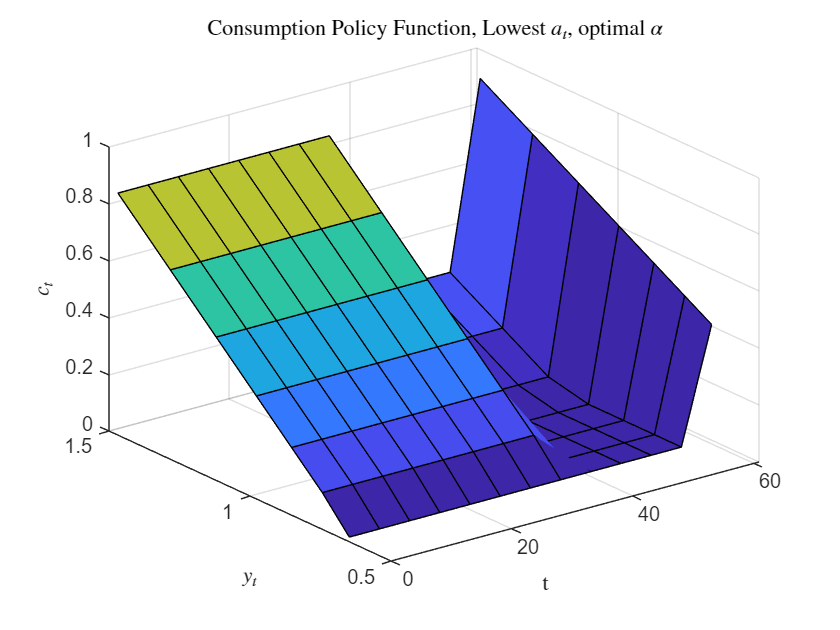

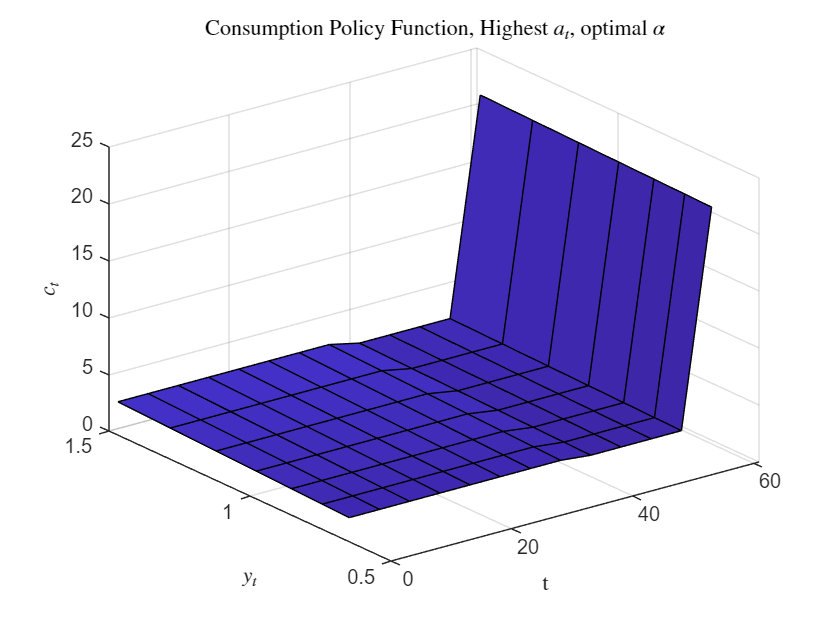

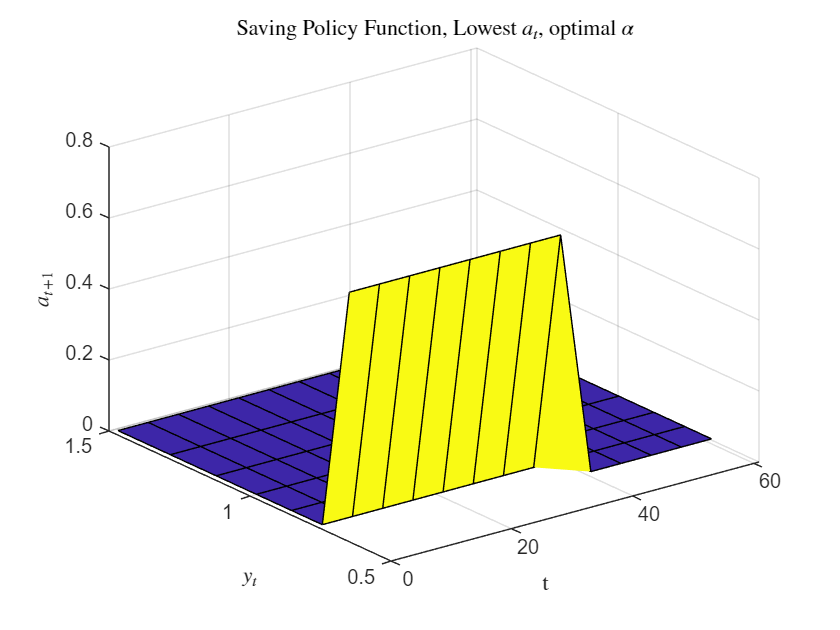

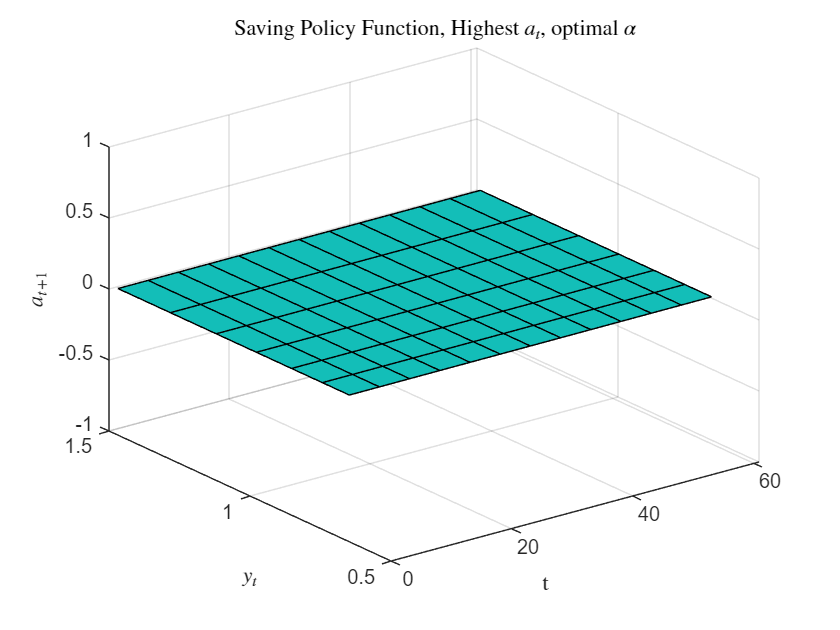

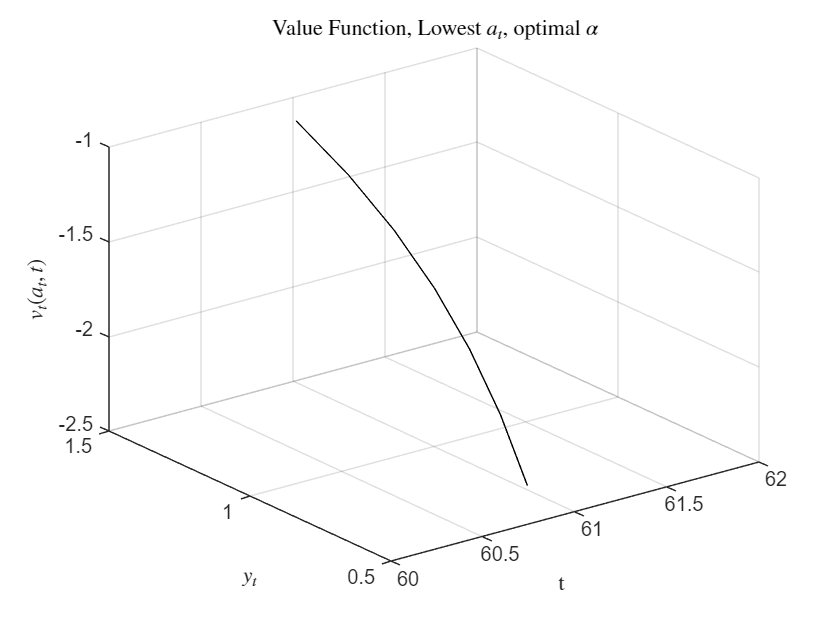

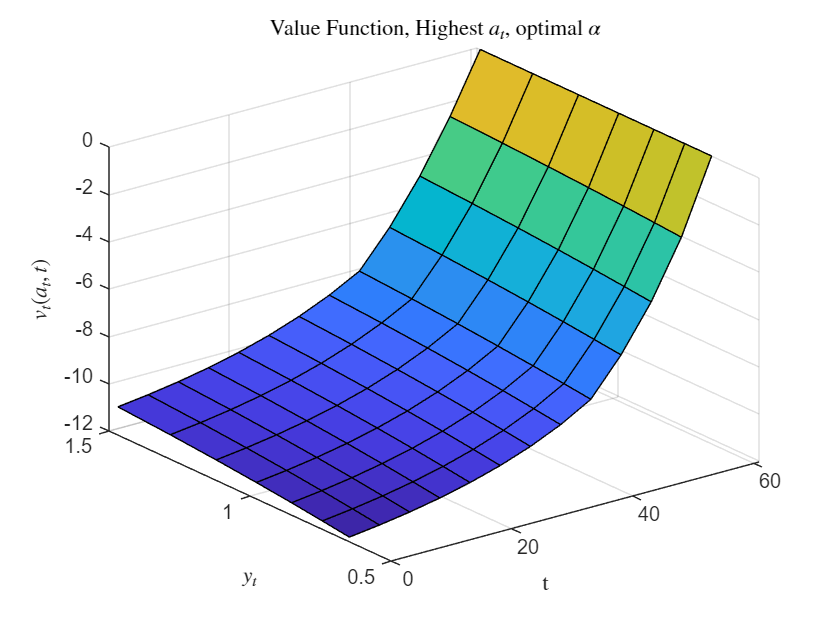

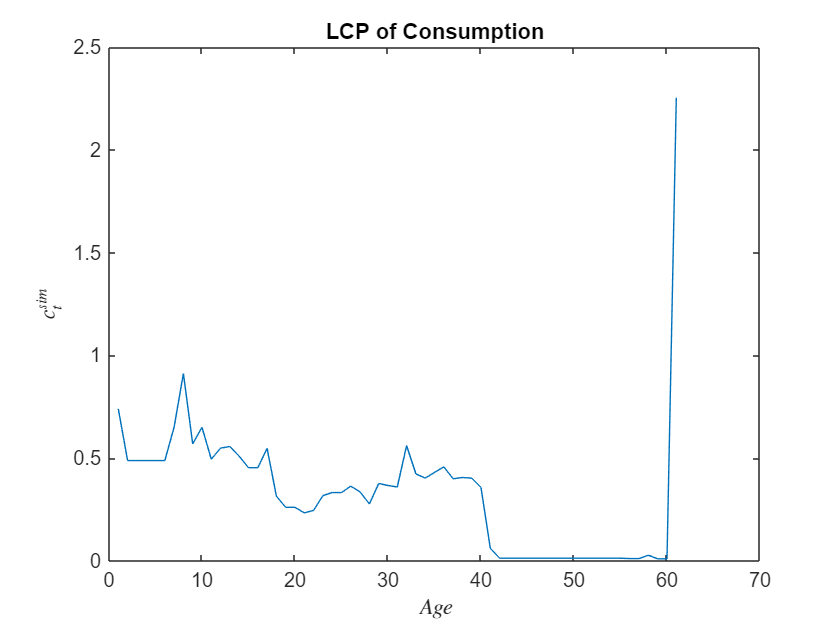

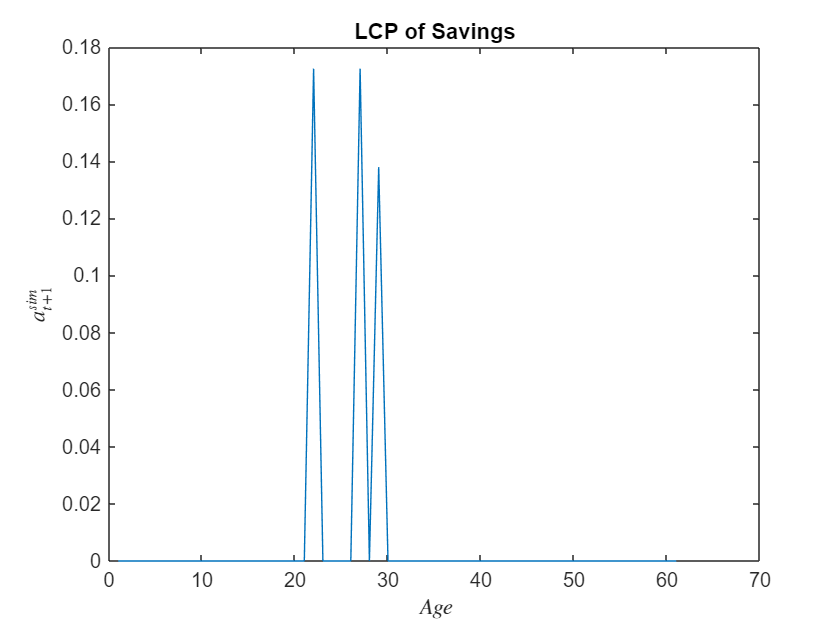

sim = djsimulate.lc(par,sol); % Simulate the model.
djmy_graph.plot_policy(par,sol,sim) % Plot the model functions and time series.